% MATLAB code to simulate a satellite orbiting the Earth

% Constants
G = 6.67430e-11;      % Gravitational constant (m^3 kg^-1 s^-2)
M = 5.972e24;         % Mass of the Earth (kg)
R = 6371e3;           % Radius of the Earth (m)

% Initial conditions
altitude = 400e3;     % Initial altitude of the satellite (m)
r0 = R + altitude;    % Initial distance from the center of the Earth (m)
orbit_type = input("Input 'e' for elliptical orbit, 'c' for circular orbit or 'p' for parabolic orbit: ", 's');
if orbit_type == "c"
    i = input("inclination: ");
    [v0,T,color] = circularOrbit(G,M,r0);
    
elseif orbit_type == "e"
    e = input("eccentricity: ");
    i = input("inclination: ");
    [v0,T,color] = ellipticalOrbit(G,M,r0,e);

elseif orbit_type == "p"
    i = input("inclination: ");
    v0 = sqrt(2* G * M / r0); % Initial orbital velocity (m/s) for circular orbit
    T = 2 * pi * sqrt(r0^3 / (G * M)); % Orbital period (s)
    color = [1 0 1];
else
    disp("Orbit type not selected");
end

% Initial position and velocity vectors
position = [r0; 0; 0];
velocity = [0; v0*cosd(i); v0*sind(i)];

% Time settings

dt = 10;                           % Time step (s)
num_steps = round(T / dt);         % Number of time steps

% Preallocate arrays for storing position and velocity
positions = zeros(3, num_steps);
velocities = zeros(3, num_steps);

% Store initial conditions
positions(:, 1) = position;
velocities(:, 1) = velocity;

%perform manoeuvres
perform_manoeuvre = input("Enter 'Y' to perform manoeuvre or 'N' to not perform manoeuvre: ", "s");
if perform_manoeuvre == "Y"
    planeChange_manoeuvre = input("Enter 'Y' to perform a plane change manoeuvre, else enter 'N': ", "s");
    if planeChange_manoeuvre == "N"    
        noOfMan = input("Enter the number of manoeuvres you would like to perform: ");
        eccentricities = zeros([noOfMan, 1]);
        for i = 1:noOfMan
            eccentricities(i,1) = input("Enter the eccentricity of the next orbit: ");
        end
        orbit_fraction = input("Enter the fraction of the orbit period you want to manoevure at: ");
        num_steps_initial = orbit_fraction*num_steps;
        numStepsOrbit = zeros([1,(noOfMan+1)]);
        numStepsOrbit(1,1) = orbit_fraction*num_steps;
    else
        i_new = input("Enter the new inclination: ");
    end
elseif perform_manoeuvre == "N"
    disp("No manoeuvres will be performed")
else
    disp("Invalid response")
end

No manoeuvres will be performed


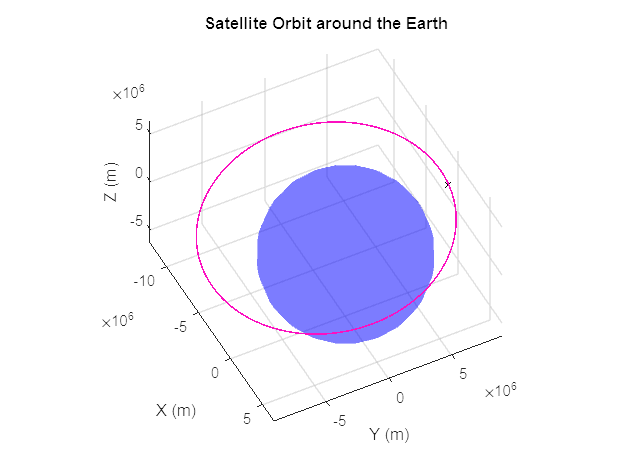

% Simulation loop
if perform_manoeuvre == "N"
    [positions, velocities] = OrbitPropagator(2,num_steps,velocities,positions,velocity);
elseif planeChange_manoeuvre == "Y"
    for m = 2:num_steps
        % Calculate acceleration due to gravity
        r = norm(position);
        acceleration = -G * M / r^3 * position;  
        % Update velocity and position using Euler's method
        velocity = velocity + acceleration * dt;
        position = position + velocity * dt;
        % Store position and velocity
        positions(:, m) = position;
        velocities(:, m) = velocity;
    end
    % New inclination after maneuver
    i_new = 60;  % degrees
    
    % Adjust the velocity for plane change
    v_magnitude = norm(velocity); % Current speed
    velocity = [0;v_magnitude*cosd(i_new); v_magnitude*sind(i_new)];  % New velocity vector
    
    % Continue integration for another orbit
    for m = num_steps+1:2*num_steps
        % Calculate acceleration due to gravity
        r = norm(position);
        acceleration = -G * M / r^3 * position;  
        % Update velocity and position using Euler's method
        velocity = velocity + acceleration * dt;
        position = position + velocity * dt;
        % Store position and velocity
        positions(:, m) = position;
        velocities(:, m) = velocity;
    end

else
    %[positions, velocities] = OrbitPropagator(2,numStepsOrbit(1,1),velocities,positions,velocity);
    for m = 2:num_steps_initial
        % Calculate acceleration due to gravity
        r = norm(position);
        acceleration = -G * M / r^3 * position;  
        % Update velocity and position using Euler's method
        velocity = velocity + acceleration * dt;
        position = position + velocity * dt;
        % Store position and velocity
        positions(:, m) = position;
        velocities(:, m) = velocity;
    end
    for j = 1:noOfMan
        if j == noOfMan
            orbit_fraction = 1;
        end
        [velocity, numStepsOrbit(1,(j+1))] = multipleOrbits(eccentricities(j,1), position, velocity, numStepsOrbit(1,j), orbit_fraction);
        for m = round(numStepsOrbit(1,j)):numStepsOrbit(1,(j+1))
            % Calculate acceleration due to gravity
            r = norm(position);
            acceleration = -G * M / r^3 * position;  
            % Update velocity and position using Euler's method
            velocity = velocity + acceleration * dt;
            position = position + velocity * dt;
            % Store position and velocity
            positions(:, m) = position;
            velocities(:, m) = velocity;
        end
    end
end

% Plot the orbit

if perform_manoeuvre == "Y"
    if planeChange_manoeuvre == "N"
        C = {'k','b','r','g','y'}; % Cell array of colours
        figure;
        hold on;
        for k = 1:noOfMan+1
            randColor = rand(1, 3); 
            if k == 1
                plot3(positions(1, 1:numStepsOrbit(1,k)), positions(2,1:numStepsOrbit(1,k)), positions(3,1:numStepsOrbit(1,k)), 'Color', randColor, 'LineWidth',1);
            else
                plot3(positions(1, numStepsOrbit(1,k-1):numStepsOrbit(1,k)), positions(2,numStepsOrbit(1,k-1):numStepsOrbit(1,k)), positions(3,numStepsOrbit(1,k-1):numStepsOrbit(1,k)), 'Color', randColor, 'LineWidth',1);
            end
        end
        for a = 1:noOfMan
            plot3(positions(1,ceil(numStepsOrbit(1,a))), positions(2,ceil(numStepsOrbit(1,a))), positions(3,ceil(numStepsOrbit(1,a))), 'h', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
        end
    else  
        figure;
        plot3(positions(1,1:num_steps), positions(2,1:num_steps), positions(3,1:num_steps), 'Color','r', 'LineWidth',1);
        hold on;
        plot3(positions(1,num_steps),positions(2,num_steps),positions(3,num_steps),'h', 'MarkerSize', 8, 'MarkerFaceColor', 'g')
        plot3(positions(1,num_steps:(2*num_steps)), positions(2,num_steps:(2*num_steps)), positions(3,num_steps:(2*num_steps)), 'Color','b', 'LineWidth',1);
    end
else
    figure;
    plot3(positions(1, 1:num_steps), positions(2, 1:num_steps), positions(3, 1:num_steps), 'Color','#FC0FC0', 'LineWidth',1);
    hold on;
end


% Plot the Earth
[X, Y, Z] = sphere;
surf(R * X, R * Y, R * Z, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
axis equal;
view([63 47])
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Satellite Orbit around the Earth');
grid on;

% % Create a small sphere
% [sphere_x, sphere_y, sphere_z] = sphere;
% sphere_radius = 100;  % Adjust the radius as needed
% sphere_x = sphere_radius * sphere_x;
% sphere_y = sphere_radius * sphere_y;
% sphere_z = sphere_radius * sphere_z;
% 
% % Initialize the sphere at the first position
% h = surf(sphere_x + positions(1, 1), sphere_y + positions(2, 1), sphere_z + positions(3, 1));
% 
% % Set the appearance of the sphere
% set(h, 'FaceColor', 'black', 'EdgeColor', 'none');  % Red sphere with no edges

% Initialize a variable to hold the marker handle
h = plot3(positions(1, 1), positions(2, 1), positions(3, 1), 'k*', 'MarkerSize', 2);  % Initial marker

% % Animation loop
% for m = 2:length(positions)
%     % Delete the previous marker
%     delete(h);
% 
%     % Plot the new marker
%     h = plot3(positions(1, m), positions(2, m), positions(3, m), 'k*', 'MarkerSize', 5);
% 
%     % Force MATLAB to render the updated plot
%     drawnow;
% 
%     % Pause to create the animation effect (adjust if needed)
%     distance = norm(positions(:,m)-positions(:,(m-1)));
%     speed = norm(velocities(:,m));
%     time = distance/speed;
%     pause(time/100);
% end


hold off;


function [v0,T,color] = circularOrbit(G,M,r0)
    v0 = sqrt(G * M / r0); % Initial orbital velocity (m/s) for circular orbit
    T = 2 * pi * sqrt(r0^3 / (G * M)); % Orbital period (s)
    color = [0.4660 0.6740 0.1880];
end

function [v0,T,color] = ellipticalOrbit(G,M,r0,e)
    a = r0/(1-e);
    v0 = sqrt(G * M * (2/r0 - 1/a)); 
    T = 2 * pi * sqrt(a^3 / (G * M)); % Orbital period (s)
    color = [0.8500 0.3250 0.0980];
end
function [newVelocity, noOfSteps] = multipleOrbits(e,currentPosition,currentVelocity,currentIter, orbitFrac)
    G = 6.67430e-11;      % Gravitational constant (m^3 kg^-1 s^-2)
    M = 5.972e24;         % Mass of the Earth (kg)
    dt = 10;
    current_velocityMag = norm(currentVelocity);
    %e_new = eccentricities(2,1);
    r_current = norm(currentPosition);
    if e == 0
        [v0,T, ~] = circularOrbit(G,M,r_current);
    else
        [v0,T, ~] = ellipticalOrbit(G,M,r_current,e);
    end
    deltaV = abs(v0-current_velocityMag);
    noOfSteps = ceil(currentIter + (round(T / dt)*orbitFrac));         % Number of time steps
    % Normalize the current velocity vector to get the direction
    v_direction = currentVelocity / current_velocityMag;
    
    % Apply the delta V in the prograde direction
    newVelocity = currentVelocity + deltaV * v_direction;
    %disp(velocity)
end
function [positions, velocities] = OrbitPropagator(noOfIterStart, noOfIterEnd,velocities,positions,velocity)
    G = 6.67430e-11;      % Gravitational constant (m^3 kg^-1 s^-2)
    M = 5.972e24;         % Mass of the Earth (kg)
    dt = 10;
    for m = round(noOfIterStart):noOfIterEnd
            position = positions(:,m-1); 
            % Calculate acceleration due to gravity
            r = norm(position);
            acceleration = -G * M / r^3 * position;  
            % Update velocity and position using Euler's method
            velocity = velocity + acceleration * dt;
            position = position + velocity * dt;
            % Store position and velocity
            positions(:, m) = position;
            velocities(:, m) = velocity;
    end
end
